## Parareal Algorithm for a system of ODEs

Test the parareal algorithm on a system of (two) ODEs (Lotka Volterra two species)

clear all; close all; clc;

### Set parameters of the ODEs system

% params
T = 300;
y0 = [15, 15];
N_coarse = 10;
dT = T/N_coarse;
dt = 0.002;
N_fine = dT/dt

N_fine = 15000

### Solve the system of ODEs

% compute first the "reference" sol
tic
[t_ref, y_ref] = ode45(@(t, y) fun(t, y), [0, T], y0);
time_ref = toc;

% compute sequential sol (only coarse solver)
tic
steps = N_coarse * N_fine;
y_seq = sequential(T, y0, steps);
time_seq = toc;

% parareal
tic
[t_par, y_par] = parareal(T, y0, N_coarse, N_fine);
time_par = toc;

### Display results

err = norm(y_ref(end,:) - y_par(end,:));
disp(['error of parareal: ' num2str(err)])

error of parareal: 1.6794


err = norm(y_ref(end,:) - y_seq(end,:));
disp(['error of sequential: ' num2str(err)])

error of sequential: 1.6489


disp(' ')

disp(['time_ref: ' num2str(time_ref)])

time_ref: 0.094871


disp(['time_seq: ' num2str(time_seq)])

time_seq: 0.1212


disp(['time_par: ' num2str(time_par)])

time_par: 9.8534


### Plots

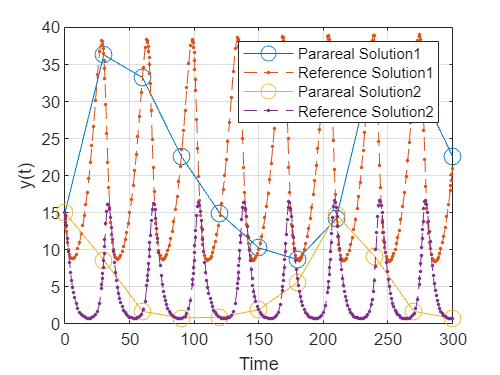

dim = length(y0);
for i=1:dim
    plot(t_par, y_par(:,i), 'o-', 'MarkerSize', 10, 'DisplayName', ['Parareal Solution', num2str(i)]);
    hold on;
    plot(t_ref, y_ref(:,i), '.--', 'DisplayName', ['Reference Solution', num2str(i)]);
end
hold off;
xlabel('Time');
ylabel('y(t)');
legend();
grid on;